# Inside the black box

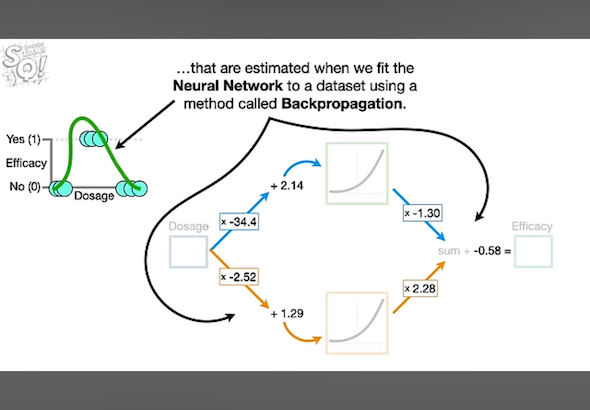

dosage = 1;
wi1 = [-34.4;-2.52];
bias1 = [2.14; 1.29];
bias2 = -0.58;
w1o = [-1.3; 2.28];

getEff(dosage, wi1, bias1, w1o, bias2)

ans = 0.0046

function efficacy = getEff(dosage, wi1, bias1, w1o, bias2)
    xs = dosage .* wi1 + bias1;
    L1 = softplus(xs);
    blueOrange = L1 .* w1o;
    greenSquiggle = sum(blueOrange);
    efficacy = greenSquiggle + bias2;
end


## Activation Function

function act = softplus(xx)
    act = log(1+exp(xx));
end
